# Derivative Rules for Combinations of Functions

As presented in [Derivative Rules for Powers](matlab:open('./derivativeRulesPolynomials.mlx')) and [Derivative Rules for Transcendental Functions](matlab:open('./derivativeRulesTranscendentals.mlx'))

**Power & Linearity Rules**                               **Transcendental Rules**            

$\frac{d}{dx}\left[x^n\right] = nx^{n-1}$   for constant $n$         $\frac{d}{dx}\left[\sin(x)\right] = \cos(x)$             $\frac{d}{dx}\left[e^x\right] = e^x$

$\frac{d}{dx}\left[cf(x)\right] = c\frac{df}{dx}$     for constant $c$         $\frac{d}{dx}\left[\cos(x)\right] = -\sin(x)$     $\frac{d}{dx}\left[\ln(x)\right] = \frac{1}{x}$      


$$\frac{d}{dx}\left[f(x)+g(x)\right] = \frac{df}{dx}+\frac{dg}{dx}$$
                                                                                                              

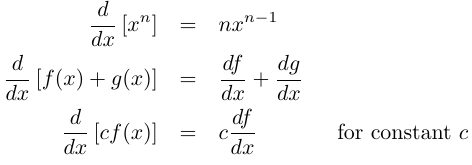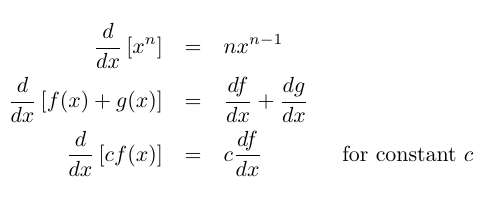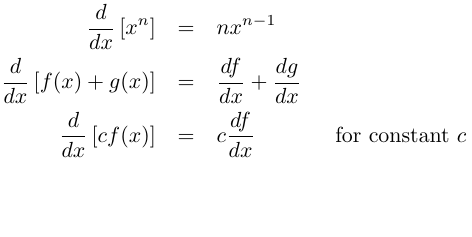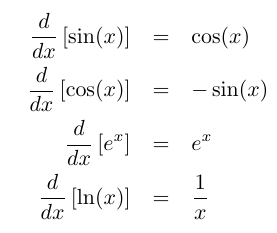With the exception of polynomials, however, most common functions are still missing from this list of rules. This script will present the two remaining fundamental rules for computing the derivatives of combinations of functions and present applications of these rules to a variety of mathematical and real-world situations.

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor window.

 Although the code is hidden, some interactivity requires familiarity with MATLAB syntax. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2 hour online tutorial that teaches the essentials of MATLAB.

## Chain Rule

Consider two functions $y = f(x)$ and $z = g(x)$. After forming a new function $y_2 = f(z) = f(g(x))$ by composing $(f \circ g)(x)$, what is the derivative? 

### Derivation of the Chain Rule

The answer depends on being a bit more specific. What is the independent variable in the question about the derivative of a function created by composing two functions? If it is $z$ there is nothing new going on:


$$\frac{dy_2}{dz} = \frac{d}{dz}\left[f(z)\right] = \frac{df}{dz} = f'(z)$$


If it is $x$, though, then:


$$\frac{dy_2}{dx} = \frac{d}{dx}\left[(f\circ g)(x)\right] = \lim_{\Delta x \to 0} \frac{f(g(x+\Delta x))-f(g(x))}{\Delta x}$$
                                                            

                                   
$$=\lim_{\Delta x\to 0} \left(\frac{f((g(x+\Delta x)-g(x))+g(x))-f(g(x))}{g(x+\Delta x)-g(x)}\right)\left(\frac{g(x+\Delta x)-g(x)}{\Delta x}\right)$$


Let $\Delta g = g(x+\Delta x) -g(x)$ denote the change in the $g$ value as a function of the change in the $x$ value $\Delta x$. Then:


$$\frac{dy_2}{dx} =\lim_{\Delta x \to 0}\left(\frac{f(g+\Delta g)-f(g)}{\Delta g}\right)\left(\frac{g(x+\Delta x)-g(x)}{\Delta x}\right)$$
    

Note that $\lim_{\Delta x \to 0} \Delta g = \lim_{\Delta x \to 0} g(x+\Delta x)-g(x) = 0$, so:

   
$$\frac{dy_2}{dx} = \left(\lim_{\Delta g \to 0} \frac{f(g+\Delta g)-f(g)}{\Delta g}\right)\left(\lim_{\Delta x \to 0}\frac{g(x+\Delta x)-g(x)}{\Delta x}\right)$$



$$=\frac{df}{dg}\cdot \frac{dg}{dx}$$
                                                             

                          
$$=f'(g)\cdot g'(x) = f'(g(x))\cdot g'(x)$$
                                                  

Visualizations:

syms x
f(x) =  x^3;
g(x) =  -.4*x+2;
a = -5;
b = 5;
if a < b 
    bds = [a, b];
else
    bds = [-5, 5];
    disp("Your lower bound is not lower than your upper bound. Using default bounds of [-5, 5].")
end
 

$f(g(x))$ is: 

disp(f(g(x)))
for x0 = linspace(bds(1),bds(2),100)
    showChainRule(@(x)f(x),@(x)g(x),x0,bds,0,1)
    pause(.2)
end

### Application: Pendulum

<Image of pendulum>

It can be shown that for small angles, the angle (from the vertical - can take this out once we have an image) as a function of time for a pendulum is:


$$\theta(t) = \theta_0 \enspace \cos \left(t\sqrt{\frac{g}{L}} \right)$$


where $g$ is acceleration due to gravity, $L$ is the length of the pendulum, and $\theta_0$ is the initial angle of the pendulum. The anglular velocity of the pendulum, $\omega(t)$, can be found by taking the derivative of $\theta(t)$ with respect to $t$. 

** Exercise**.

- Find the expression for angular velocity $\frac{d\theta}{dt} = \omega(t)$. 

-  Based on your knowledge of a pendulum, where would you expect the angular velocity to be zero? After thinking about this, use the expression you just found for $\omega(t)$and find a time (other than $t = 0$) where the pendulum is at rest. At this time, what is the value of $\theta(t)$? Is it where you would expect it to be?

- Similarly, the angular acceleration, $\alpha(t)$, of the pendulum can be found as the derivative of the angular velocity with respect to time. Find the expression for angular acceleration $\frac{d^2\theta}{dt^2}=\alpha(t)$. 

clickedPendulumAnswers= false;
showPendulumAnswers(clickedPendulumAnswers);

### Application: Related Rates

Consider a classic record that rotates at 45 rotations per minute. 

figure
theta = linspace(0,25*pi,10000);
plot(7/80*(theta(1:800)+1).*sin(6*theta(1:800)),7/80*(theta(1:800)+1).*cos(6*theta(1:800)),"r-")
hold on
plot(7/80*(theta+6.726).*sin(6*(theta)),7/80*(theta+6.726).*cos(6*(theta)),"k-")
hold off
axis equal off
title("A representation of a classic 7 inch 45")
 

This rotational speed means that $\frac{d\theta}{dt}$ is a constant. In fact, 45 rotations per minute means 

$\frac{d\theta}{dt}$ = $45*2\pi/60$ radians per second = $\frac{3\pi}{2}$ radians per second.

If we start a needle from the inner edge of the record, that is for $\theta=0$ radians, when $r(\theta) = \frac{7}{80}\sqrt{(\theta+6.726)^2}$ inches and observe it as it progresses towards the outer edge, at what speed in inches per second is it moving away from the center, i.e. what is $\frac{dr}{dt}$, after 45 seconds of playing time?

speed =  0;
checkSpeed(speed);
 

### Practice Chain Rule Problems

Choose a variable and generate a product rule problem:

[myFun, varChoice, ~, ~, ~] = genProbType(varOpts,3);
totProbs = totProbs+1;
 

myAnswer = t;
[lastFive,errorCount] = check1(myFun, varChoice, myAnswer, errorCount,lastFive);
 

Once you have completed sufficient practice, track the overall results of your practice here:

 
pctTypeWrong = errorCount./totProbs*100;
overallRight = (1-sum(errorCount)/sum(totProbs))*100;
if min(totProbs) >= 5
    lastCorrect = sum(lastFive,2);
    str = compose("My overall success rate is %.1f%% on %i total problems \n\n" + ...
        "Of the last five, %i were correct.",overallRight,sum(totProbs),lastCorrect);
else
    str = compose("My overall success rate is %.1f%% on %i total problems \n\n" + ...
        "Please do at least five problems.",overallRight, sum(totProbs));
end

disp(str)

## Product Rule

syms x
f = symfun(3*x+1,x);
g = symfun(2*x^2-x+2,x);
pt = 3;
h = 0.05;
 
showAnimation = false; showFG = true ; showChange = true; showdfdg = true;
if ~any([showAnimation showFG showChange showdfdg])
    showProductRule(f, g, pt, h, ["#4DBEEE","#A2142F","#77AC30"])
end
if showAnimation
animateProductRule(f,g,pt,h,["#4DBEEE","#A2142F","#77AC30"])
end

if any([showFG showChange showdfdg])
    showProductRule(f,g,pt,h,["#4DBEEE","#A2142F","#77AC30"])
end
if showFG && ~any([showChange showdfdg])
    annProdfg(f,g,pt,h,0)
elseif showFG
    annProdfg(f,g,pt,h,1)
end
if showChange 
    annProdChange(f,g,pt,h,"#77AC30")
end
if showdfdg
    annProddfdg(f,g,pt,h,"#A2142F")
end

### Practice Product Rule Problems

syms t r x z C
varOpts = [t r x z];
maxProbIdx = 1
errorCount = zeros(1,maxProbIdx);
totProbs = zeros(1,maxProbIdx);
lastFive = zeros(maxProbIdx,5);
 

Choose a variable and generate a product rule problem:

[myFun, varChoice, probType, a, b] = genProbType(varOpts,2);
totProbs = totProbs+1;
 

myAnswer = -60*x^4*sin(4*x-1)-12*x^5*cos(4*x-1)*4;
[lastFive,errorCount] = check1(myFun, varChoice, myAnswer, errorCount,lastFive);
 

Once you have completed sufficient practice, track the overall results of your practice here:

pctTypeWrong = errorCount./totProbs*100;
overallRight = (1-sum(errorCount)/sum(totProbs))*100;
if min(totProbs) >= 5
    lastCorrect = sum(lastFive,2);
    str = compose("My overall success rate is %.1f%% on %i total problems \n\n" + ...
        "Of the last five, %i were correct.",overallRight,sum(totProbs),lastCorrect);
else
    str = compose("My overall success rate is %.1f%% on %i total problems \n\n" + ...
        "Please do at least five problems.",overallRight, sum(totProbs));
end

disp(str)

### Application: Lamellophone

### Application: Quotient Rule

One common combination of functions that deserves mention is $\frac{f(x)}{g(x)}$ for some functions $f(x)$ and $g(x)$ where $g(x)\neq 0$. Take the derivative:


$$\frac{d}{dx}\left[\frac{f(x)}{g(x)}\right] =  \frac{d}{dx}\left[f(x)\cdot \left(\frac{1}{g(x)}\right)\right] = \frac{d}{dx}\left[f(x)\cdot \left(g(x)\right)^{-1}\right]$$
          

Applying the product rule, 

$\frac{d}{dx}\left[\frac{f(x)}{g(x)}\right] = \frac{d}{dx}\left[f(x)\right]\cdot \left(g(x)\right)^{-1}+f(x)\cdot\left(\frac{d}{dx}\left[\left(g(x)\right)^{-1}\right]\right)$.      

Applying the chain rule,


$$\frac{d}{dx}\left[\frac{f(x)}{g(x)}\right] = \frac{d}{dx}\left[f(x)\right]\cdot (g(x))^{-1} + f(x)\left(-(g(x))^{-2}\frac{d}{dx}\left[g(x)\right]\right)$$


and simplifying:

$\frac{d}{dx}\left[\frac{f(x)}{g(x)}\right] = \frac{f'(x)}{g(x)}-\frac{f(x)g'(x)}{(g(x))^2} = \frac{f'(x)g(x)-f(x)g'(x)}{(g(x))^2}$.         

### Practice Mixed Derivative Problems

syms t r x z C
varOpts = [t r x z];
maxProbIdx = 3
errorCount = zeros(1,maxProbIdx);
totProbs = zeros(1,maxProbIdx);
lastFive = zeros(maxProbIdx,5);
 

Choose a variable and generate a problem:

[myFun, varChoice, probType, a, b] = genProb(varOpts);
totProbs(probType) = totProbs(probType)+1;
 

myAnswer = -4*49/r^5;
[lastFive,errorCount] = check(myFun, varChoice, myAnswer, probType,errorCount,lastFive);
 

Once you have completed sufficient practice, track the overall results of your practice here:

 
giveFeedback(errorCount,totProbs,lastFive)
pctTypeWrong = errorCount./totProbs*100;
overallRight = (1-sum(errorCount)/sum(totProbs))*100;
if min(totProbs) >= 5
    lastCorrect = sum(lastFive,2);
    str = compose("My overall success rate is %.1f%% on %i total problems \n\n" + ...
        "Breaking down by type: \n\nSimple derivatives: \n %i problems of which %.1f%% were wrong. \n " + ...
        "Of the last five, %i were correct. \n\n" + ...
        "Product Rule derivatives: \n %i problems of which %.1f%% were wrong. \n " + ...
        "Of the last five, %i were correct. \n\n" + ...
        "Chain Rule derivatives: \n %i problems of which %.1f%% were wrong. \n " + ...
        "Of the last five, %i were correct." ...
        ,overallRight, sum(totProbs),totProbs(1),pctTypeWrong(1),lastCorrect(1),totProbs(2),pctTypeWrong(2) ...
        ,lastCorrect(2),totProbs(3),pctTypeWrong(3),lastCorrect(3));
else
    str = compose("My overall success rate is %.1f%% on %i total problems \n\n" + ...
        "Breaking down by type: \n\n Simple derivatives: \n %i problems of which %.1f%% were wrong.\n\n" + ...
        "Product Rule derivatives: \n %i problems of which %.1f%% were wrong. \n\n" + ...
        "Chain Rule derivatives: \n %i problems of which %.1f%% were wrong." ...
        ,overallRight, sum(totProbs),totProbs(1),pctTypeWrong(1),totProbs(2),pctTypeWrong(2) ...
        ,totProbs(3),pctTypeWrong(3));
end

disp(str)
if min(totProbs) < 5 || min(pctTypeWrong)>15
    disp("It is probably a good idea to keep practicing.")
    disp("Can you get 5 problems right of each type?")
elseif min(totProbs)>= 5 && max(pctTypeWrong)>10
    [mval idx] = max(pctTypeWrong);
    strChoice = ["simple derivatives","product rule derivatives","chain rule derivatives"];
    disp("Perhaps you want to review " + strChoice(idx) + " since you are having particular trouble with them?")
    disp("Of the last five " + strChoice(idx) + " that you have done, you scored " + sum(lastFive(idx,:))  + "/5.")
    if sum(lastFive(idx,:)) == 5
        disp("You seem to have figured " + strChoice(idx) + " out better.")
        [minVal mIdx] = min(sum(lastFive,2));
        if minVal < 5
            disp("Perhaps you should work on " + strChoice(mIdx) + "now?")
        end
    end
elseif max(pctTypeWrong) > 0
    disp("Is there a particular type of problem you are struggling with?")
else
    disp("Good work! Practice is what builds fluency and you appear to have been doing the work.")
end

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor window.

function showChainRule(fh,gh,pt,bds,opt1,opt2)
    syms x
    df(x) = diff(fh(x),x);
    dg(x) = diff(gh(x),x);
    dchain(x) = diff(fh(gh(x)), x);
    step0 = (bds(2)-bds(1))/1000;
    xVals = bds(1):step0:bds(2);
    gVals = double(gh(xVals));
    fVals = double(fh(gVals));
    xMin = pt-2*step0;
    xMax = pt+12*step0;
    dfdx = double(df(gh(pt))*dg(pt));
    dgdx = double(dg(pt));
    fpt = double(fh(gh(pt)));
    gpt = double(gh(pt));
    if opt1
        gMin = min([double(gh(xMin)) double(gh(xMax))]);
        gMax = max([double(gh(xMin)) double(gh(xMax))]);
        fMin = min([double(fh(gMin)) double(fh(gMax))]);
        fMax = max([double(fh(gMin)) double(fh(gMax))]);
    for k = 10:-1:1
        h = k*step0;
        tLayout = tiledlayout(2,2);
        approxdfdg = double((fh(gh(pt+h))-fh(gh(pt)))/(gh(pt+h)-gh(pt)));
        approxdgdx = double((gh(pt+h)-gh(pt))/h);
        approxdfdx = approxdfdg*approxdgdx;
        title(tLayout,"$\frac{df}{dx} = \frac{df}{dg}\frac{dg}{dx} = $"+dfdx,"Interpreter","latex")
        xlabel(tLayout,"h = "+h)
        nexttile
        plot(gVals,fVals)
        xlim([gMin gMax])
        ylim([fMin fMax])
        hold on
        xline(double(gh(pt)),"r-","LineWidth",2)
        xline(double(gh(pt+h)),"b--")
        yline(double(fh(gh(pt))),"r-","LineWidth",2)
        yline(double(fh(gh(pt+h))),"b--")
        hold off
        xlabel("$g$","Interpreter","latex")
        ylabel("$f(g)$","Interpreter","latex")
        title("$\frac{\Delta f}{\Delta g} = $" + approxdfdg,"Interpreter","latex")
       nexttile
       fplot(x,fh(x),bds)
       hold on
       fplot(x,gh(x),bds)
       plot([xMin xMax],gpt+approxdgdx.*([gMin gMax]-gpt),"g--")
       plot([gMin gMax],fpt+approxdfdg.*([fMin fMax]-fpt),"m--")
       ylim([-22 22])
       hold off
       xlabel("$x$","Interpreter","latex")
       legend(["$f(x)$" "$g(x)$"],"Interpreter","latex","Location","best")
    nexttile
        plot(gVals,gVals)
        yline(double(gh(pt)),"r-","LineWidth",2)
        yline(double(gh(pt+h)),"b--")
        xline(double(gh(pt)),"r-","LineWidth",2)
        xline(double(gh(pt+h)),"b--")
        xlim([gMin gMax])
        ylim([gMin gMax])
    title("$\frac{\Delta g}{\Delta g} = 1$","Interpreter","latex")
        nexttile
        plot(xVals,gVals)
        ylim([gMin gMax])
        xlim([xMin xMax])
        hold on
        xline(pt,"r-","LineWidth",2)
        xline(pt+h,"b:")
        yline(double(gh(pt)),"r-","LineWidth",2)
        yline(double(gh(pt+h)),"b--")
        hold off
        title("$\frac{\Delta g}{\Delta x} = $" + approxdgdx,"Interpreter","latex")
        pause(.2)
    end
    end
if opt2
    xMin = bds(1);
    xMax = bds(2);
    gMin = min(gVals);
    gMax = max(gVals);
    fMin = min(fVals);
    fMax = max(fVals);
    fdiff = .1*(fMax-fMin);
    gdiff = .1*(gMax-gMin);
    dfdg = double(df(gpt));
    tLayout2 = tiledlayout(2,2);
    title(tLayout2,"When $x_0$ = "+pt+", then $\frac{df}{dg}\frac{dg}{dx} = ($"+dfdg+"$)\cdot($"+dgdx+"$) = $"+dfdx,"Interpreter","latex")
    nexttile(tLayout2,1)
    fplot(x,fh(x),[gMin gMax])
    hold on
    graphTangent(@(x) fh(x), gpt, [gMin gMax])
    hold off
    xlabel("$g$","Interpreter","latex")
    ylabel("$f(g)$","Interpreter","latex")
    title("$\frac{df}{dg} = $" + dfdg,"Interpreter","latex")
    ylim([fMin-fdiff fMax+fdiff])
    nexttile(tLayout2,2,[2 1])
    fplot(x,fh(gh(x)),bds)
    hold on
    graphTangent(@(x)fh(gh(x)), pt, bds)
    hold off
    xlabel("$x$","Interpreter","latex")
    ylabel("$f(g(x))$","Interpreter","latex")
    title("$\frac{df}{dx} = $"+dfdx,"Interpreter","latex")
    ylim([fMin-fdiff fMax+fdiff])
    nexttile(tLayout2,3)
    fplot(x,gh(x),bds)
    hold on
    graphTangent(@(x) gh(x),pt,bds)
    hold off
    xlabel("$x$","Interpreter","latex")
    ylabel("$g(x)$","Interpreter","latex")
    title("$\frac{dg}{dx} = $" + dgdx,"Interpreter","latex")
    ylim([gMin-gdiff gMax+gdiff])
end
end

function graphTangent(fh, pt, bds)
    syms x 
    df(x) = diff(fh(x), x);
    x0 = pt;
    fplot(df(x0)*(x-x0)+fh(x0), bds)
end

function showPendulumAnswers(click)
    u = symunit;
    if ~click
        clear tOmegaIsZero omega alpha theta_0 g L
    else
        syms theta_0 t g L
        assume(t > 0 & g/L > 0)
        theta = theta_0 * cos(t * sqrt(g/L));
        disp("The answer to Exercise 1. is:")
        omega = diff(theta,t)
        disp(" ")
        disp("The answer to Exercise 2. is:")
        tOmegaIsZero = u.sec * solve(omega == 0,'ReturnConditions',false)
        pendulumStoppedAngle = subs(theta,t,separateUnits(tOmegaIsZero))
        disp("The pendulum will stop at the same angle that it was released from, but on the other side!")
        disp("Any time the pendulum reaches this angle (the maximum angle), it should be at rest.")
        disp(" ")
        disp("The answer to Exercise 3. is: ")
        alpha = diff(omega,t)
        out = 1;
    end
end

function [fx,fxph,gx,gxph] = calcPointVals(f,g,pt,h)
    syms x
    fx = double(f(pt));
    fxph = double(f(pt+h));
    gx = double(g(pt));
    gxph = double(g(pt+h));
end

function [zxs,zys,fxs,fxphs,gxs,gxphs] = calcScaledPointVals(fx,fxph,gx,gxph,ax)
    xlimits = ax.XLim;
    ylimits = ax.YLim;
    axInnerPosition = ax.InnerPosition;
    yScale = axInnerPosition(4);
    xScale = axInnerPosition(3);
    x0 = axInnerPosition(1);
    y0 = axInnerPosition(2);
    xMin = xlimits(1);
    xMax = xlimits(2);
    yMin = ylimits(1);
    yMax = ylimits(2);
    zxs = -xMin/(xMax-xMin)*xScale+x0;
    zys = -yMin/(yMax-yMin)*yScale+y0;
    fxs = (fx-xMin)/(xMax-xMin)*xScale+x0;
    gxs = (gx-yMin)/(yMax-yMin)*yScale+y0;
    fxphs = (fxph-xMin)/(xMax-xMin)*xScale+x0;
    gxphs = (gxph-yMin)/(yMax-yMin)*yScale+y0;
end

function showProductRule(f, g, pt, h, cols)
    [fx,fxph,gx,gxph] = calcPointVals(f,g,pt,h);
    scatter([0 fx fx 0], [0 0 gx gx],"white")
    xRange = abs(max([0,fx,fxph])-min([0,fx,fxph]));
    yRange = abs(max([0,gx,gxph])-min([0,gx,gxph]));
    [xstart,ystart,dx,dy] = findCoords(0,0,fx,gx);
    rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",cols(1),"EdgeColor","k")
    [xstart,ystart,dx,dy] = findCoords(fx,0,fxph-fx,gx);
    rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",cols(3),"EdgeColor","k")
    [xstart,ystart,dx,dy] = findCoords(0,gx,fx,gxph-gx);
    rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",cols(3),"EdgeColor","k")
    [xstart,ystart,dx,dy] = findCoords(fx,gx,fxph-fx,gxph-gx);
    rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",cols(2),"EdgeColor","k")
    title("Product Rule")
    xlabel("$f(x)$","Interpreter","latex")
    ylabel("$g(x)$","Interpreter","latex")
end

function mpt = findMidPt(opt1,opt2)
    mpt = min([opt1 opt2])+.5*abs(opt2-opt1);
end

function [xpt,ypt] = findMidCoords(xopt1,xopt2,yopt1,yopt2,xshift,yshift)
    if xshift < 0
        xpt = max([findMidPt(xopt1,xopt2)+xshift min([xopt1 xopt2])]);
    else
        xpt = max([min([findMidPt(xopt1,xopt2)+xshift max([xopt1 xopt2])-.1]) 0]);
    end
    if yshift < 0
        ypt = max([findMidPt(yopt1,yopt2)+yshift min([yopt1 yopt2])]);
    else
        ypt = max([min([findMidPt(yopt1,yopt2)+yshift max([yopt1 yopt2])-.1]) 0]);
    end
end

function [xpt,ypt,zxs,zys] = setMidPts(f,g,pt,h)
    ax = gca;
    [fx,fxph,gx,gxph] = calcPointVals(f,g,pt,h);
    [zxs,zys,fxs,fxphs,gxs,gxphs] = calcScaledPointVals(fx,fxph,gx,gxph,ax);
    [xpt,ypt] = findMidCoords(zxs,fxs,zys,gxs,-.1,-.1);
end

function [fLxs,fFxs,gLxs,gFxs] = setBndryPts(f,g,pt,h)
    ax = gca;
    [fx,fxph,gx,gxph] = calcPointVals(f,g,pt,h);
    [zxs,zys,fxs,fxphs,gxs,gxphs] = calcScaledPointVals(fx,fxph,gx,gxph,ax);
    if abs(fxphs-zxs)>abs(fxs-zxs)
        fLxs = fxs;
        fFxs = fxphs;
    else
        fLxs = fxphs;
        fFxs = fxs;
    end
    if abs(gxphs-zys)>abs(gxs-zys)
        gLxs = gxs;
        gFxs = gxphs;
    else
        gLxs = gxphs;
        gFxs = gxs;
    end
end

function annProdfg(f,g,pt,h,choice)
    [xpt,ypt,zxs,zys] = setMidPts(f,g,pt,h);
    if choice
        dim = [findMidPt(xpt,zxs) findMidPt(ypt,zys) .216 .05];
    else
        dim = [xpt ypt .216 .05];
    end
    annotation("textbox",dim,"String","Area = $f(x)\cdot g(x)$","Interpreter","latex")
end

function annProddfdg(f,g,pt,h,col2)
    [xpt,ypt] = setMidPts(f,g,pt,h);
    [fLxs,fFxs,gLxs,gFxs] = setBndryPts(f,g,pt,h);
    [xUpt,yUpt] = findMidCoords(xpt,fFxs,ypt,gFxs,0,0);
    annotation("textarrow",[xUpt fLxs],[yUpt gLxs],"String","$\Delta f \cdot \Delta g$","TextEdgeColor",col2,"Color",col2,"Interpreter","latex")
end

function annProdChange(f,g,pt,h,col3)
    [xpt,ypt,zxs,zys] = setMidPts(f,g,pt,h);
    [fLxs,fFxs,gLxs,gFxs] = setBndryPts(f,g,pt,h);
    [xUpt,yUpt] = findMidCoords(xpt,fFxs,ypt,gFxs,0,0);
    if fLxs > xpt && gLxs > ypt
        yNpt = ypt;
        xNpt = xpt;
    elseif fLxs < xpt && gLxs > ypt
        yNpt = ypt;
        xNpt = findMidPt(xpt,zxs);
    elseif fLxs > xpt && gLxs < ypt
        yNpt = findMidPt(ypt,zys);
        xNpt = xpt;
    else
        yNpt = findMidPt(ypt,zys);
        xNpt = findMidPt(xpt,zxs);
    end
    annotation("textarrow",[xUpt fLxs],[yNpt yNpt],"String","$\Delta f \cdot g(x)$","TextEdgeColor",col3,"Interpreter","latex")
    annotation("textarrow",[xNpt xNpt],[yUpt gLxs],"String","$f(x) \cdot \Delta g$","TextEdgeColor",col3,"Interpreter","latex")
end

function animateProductRule(f,g,pt,h,cols)
    [fx,fxph,gx,gxph] = calcPointVals(f,g,pt,h);
    showProductRule(f,g,pt,h,cols)
    pause(2)
    col1 = cols(1);
    col2 = cols(2);
    col3 = cols(3);
    showProductRule(f,g,pt,h,[col1 "none" "none"])
    annProdfg(f,g,pt,h,0)
    pause(3)
    showProductRule(f,g,pt,h,["none" col2 "none"])
    annProddfdg(f,g,pt,h,col2)
    pause(3)
    showProductRule(f,g,pt,h,["none" "none" col3])
    annProdChange(f,g,pt,h,col3)
    pause(3)
    showProductRule(f, g, pt, h, cols)
    annProdfg(f,g,pt,h,1)
    annProddfdg(f,g,pt,h,col2)
    annProdChange(f,g,pt,h,col3)
end

function [x0,y0,dx,dy] = findCoords(x0,y0,dx,dy)
    if dx < 0
        x0 = double(x0+dx);
        dx = double(abs(dx));
    end
    if dy < 0
        y0 = double(y0+dy);
        dy = double(abs(dy));
    end
end

function [myFun, varChoice, probType, a, b] = genProb(varOpts)
% genProb sets up a variable and generates a randomized function
% 
% Inputs: varOpts is an array of possible variables
%         probType is a string that identifies the function type
% Outputs: myFun is a symbolic function
%          varChoice is the independent variable
%          probType is an integer tracking the type of question asked
%          [a, b] are the bounds for the definite integral, if required
varChoice = varOpts(randi([1 length(varOpts)], 1));
probType = randi([1 3], 1);
a = 0; 
b = 0;
switch probType
    case 1 % Simple derivative
        myFun = genFunDiff(varChoice, [1, 10]);
        disp("Take the derivative with respect to: ")
        disp(varChoice) 
        disp(" of the function f = ") 
        disp(myFun)
    case 2 % Product rule derivative
        syms f(x) g(x)
        f(x) = genFunDiff(x, [1, 7]);
        g(x) = genFunDiff(x, [1, 7]);
        myFun = f(varChoice)*g(varChoice);
        disp("Take the derivative with respect to: ")
        disp(varChoice)
        disp(" of the function f = ")
        disp(myFun)
    case 3 % Chain rule derivative
        syms f(x) g(x)
        f(x) = genFunDiff(x, [1, 3]);
        g(x) = genFunDiff(x, [1, 5]);
        myFun = f(g(varChoice));
        disp("Take the derivative with respect to: ")
        disp(varChoice)
        disp(" of the function f = ")
        disp(myFun)
end
end

function [myFun, varChoice, probType, a, b] = genProbType(varOpts, probTypeSelected)
% genProb sets up a variable and generates a randomized function
% 
% Inputs: varOpts is an array of possible variables
%         probType is a string that identifies the function type
% Outputs: myFun is a symbolic function
%          varChoice is the independent variable
%          probType is an integer tracking the type of question asked
%          [a, b] are the bounds for the definite integral, if required
varChoice = varOpts(randi([1 length(varOpts)], 1));
probType = probTypeSelected;
a = 0; 
b = 0;
switch probType
    case 1 % Simple derivative
        myFun = genFunDiff(varChoice, [1, 10]);
        disp("Take the derivative with respect to: ")
        disp(varChoice) 
        disp(" of the function f = ") 
        disp(myFun)
    case 2 % Product rule derivative
        syms f(x) g(x)
        f(x) = genFunDiff(x, [1, 7]);
        g(x) = genFunDiff(x, [1, 7]);
        myFun = f(varChoice)*g(varChoice);
        disp("Take the derivative with respect to: ")
        disp(varChoice)
        disp(" of the function f = ")
        disp(myFun)
    case 3 % Chain rule derivative
        syms f(x) g(x)
        f(x) = genFunDiff(x, [1, 3]);
        g(x) = genFunDiff(x, [1, 5]);
        myFun = f(g(varChoice));
        disp("Take the derivative with respect to: ")
        disp(varChoice)
        disp(" of the function f = ")
        disp(myFun)
end
end

function myFun = genFunDiff(var,bds)
% genFunDiff generates a random function with a simple derivative
% 
% Inputs: var is the independent variable
%         bds is a 1x2 vector of increasing integer values that set 
%             the range for the coefficients
%         fType is an integer that identifies the type of function
% Outputs: myFun is the generated symbolic function
syms f(t) 
params = randi(bds,[1,5]);
sgn1 = randi([0 1], 1);
sgn2 = randi([0 1], 1);
sgn3 = randi([0 1], 1);
type = randi([1 6], 1);

a = (-1)^sgn1*params(1);
b = (-1)^sgn2*params(2);
c = max(params(3),params(5)); 
d = (-1)^sgn3*params(4);

switch type
    case 1
        f(t) = a*t^(b);
    case 2
        f(t) = a*t^(b/c);
    case 3
        f(t) = a*exp(b*t);
        disp("Remember that exp(x) is the notation for e^x in MATLAB.")
    case 4
        f(t) = a*log(abs(b)*t);
        disp("Remember that log(x) is the notation for a natural logarithm in MATLAB.")
    case 5
        f(t) = a*sin(b*t+d);
    case 6
        f(t) = a*cos(b*t+d);
end

myFun = f(var);
end

function [lastFive,errorCount] = check(myFunc,myVar,myAnswer,probType,errorCount,lastFive)
% check generates correct answers by differentiating or integrating
%
% Inputs: myFunc is the symbolic function to differentiate or integrate
%         myVar is the independent variable
%         myAnswer is the symbolic test function or number
%         probType is an integer that tracks the question asked
%         bds is a 1x2 vector giving the bounds for definite integration
% Output: correctAnswer is a symbolic function that is the 
%         solution to probType applied to myFunc(myVar) with bds
syms C
correctAnswer = diff(myFunc,myVar);
lastFive(probType,1:4) = lastFive(probType,2:5);
disp("When simplified, my answer is: ")
disp(myAnswer)
if correctAnswer == myAnswer
    disp("My answer is correct.")
    lastFive(probType,5) = 1;
else
    switch probType
        case 1
            disp("My answer is incorrect. The correct answer is:");
            correctAnswer
            errorCount(probType) = errorCount(probType)+1;
            disp("Please try again with a new problem.")
        case 2
            disp("My answer is incorrect. This was a product rule question.")
            disp("The correct answer is:");
            correctAnswer
            disp("Please try again with a new problem.")
            errorCount(probType) = errorCount(probType)+1;
        case 3
            disp("My answer is incorrect. This was a chain rule question.")
            disp("The correct answer is:");
            correctAnswer
            disp("Please try again with a new problem.")
            errorCount(probType) = errorCount(probType)+1;
    end
            lastFive(probType,5) = 0;
end
end

function [lastFive,errorCount] = check1(myFunc,myVar,myAnswer,errorCount,lastFive)
% check generates correct answers by differentiating or integrating
%
% Inputs: myFunc is the symbolic function to differentiate or integrate
%         myVar is the independent variable
%         myAnswer is the symbolic test function or number
%         probType is an integer that tracks the question asked
%         bds is a 1x2 vector giving the bounds for definite integration
% Output: correctAnswer is a symbolic function that is the 
%         solution to probType applied to myFunc(myVar) with bds
syms C
correctAnswer = diff(myFunc,myVar);
lastFive(1:4) = lastFive(2:5);
disp("When simplified, this function is: ")
disp(myAnswer)
if correctAnswer == myAnswer
    disp("That answer is correct.")
    lastFive(5) = 1;
else
    disp("That is incorrect. The correct answer is:");
    correctAnswer
    errorCount = errorCount+1;
    disp("Please try again with a new problem.")
    lastFive(5) = 0;
end
end

function giveFeedback(errorCount,totProbs,lastFive)
    pctTypeWrong = errorCount./totProbs*100;
    overallRight = (1-sum(errorCount)/sum(totProbs))*100;
    if min(totProbs) >= 5
        lastCorrect = sum(lastFive,2);
        str = compose("My overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Breaking down by type: \n\nSimple derivatives: \n %i problems of which %.1f%% were wrong. \n " + ...
            "Of the last five, %i were correct. \n\n" + ...
            "Product Rule derivatives: \n %i problems of which %.1f%% were wrong. \n " + ...
            "Of the last five, %i were correct. \n\n" + ...
            "Chain Rule derivatives: \n %i problems of which %.1f%% were wrong. \n " + ...
            "Of the last five, %i were correct." ...
            ,overallRight, sum(totProbs),totProbs(1),pctTypeWrong(1),lastCorrect(1),totProbs(2),pctTypeWrong(2) ...
            ,lastCorrect(2),totProbs(3),pctTypeWrong(3),lastCorrect(3));
    else
        str = compose("My overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Breaking down by type: \n\n Simple derivatives: \n %i problems of which %.1f%% were wrong.\n\n" + ...
            "Product Rule derivatives: \n %i problems of which %.1f%% were wrong. \n\n" + ...
            "Chain Rule derivatives: \n %i problems of which %.1f%% were wrong." ...
            ,overallRight, sum(totProbs),totProbs(1),pctTypeWrong(1),totProbs(2),pctTypeWrong(2) ...
            ,totProbs(3),pctTypeWrong(3));
    end
    
    disp(str)
    if min(totProbs) < 5 || min(pctTypeWrong)>15
        disp("It is probably a good idea to keep practicing.")
        disp("Can you get 5 problems right of each type?")
    elseif min(totProbs)>= 5 && max(pctTypeWrong)>10
        [mval idx] = max(pctTypeWrong);
        strChoice = ["simple derivatives","product rule derivatives","chain rule derivatives"];
        disp("Perhaps you want to review " + strChoice(idx) + " since you are having particular trouble with them?")
        disp("Of the last five " + strChoice(idx) + " that you have done, you scored " + sum(lastFive(idx,:))  + "/5.")
        if sum(lastFive(idx,:)) == 5
            disp("You seem to have figured " + strChoice(idx) + " out better.")
            [minVal mIdx] = min(sum(lastFive,2));
            if minVal < 5
                disp("Perhaps you should work on " + strChoice(mIdx) + "now?")
            end
        end
    elseif max(pctTypeWrong) > 0
        disp("Is there a particular type of problem you are struggling with?")
    else
        disp("Good work! Practice is what builds fluency and you appear to have been doing the work.")
    end
end

function checkSpeed(drdt)
syms dr dt dtheta    
theta = 45*45*2*pi/60;
    answer = 7/80*(1/2)*((theta+6.726)^2)^(-1/2)*2*(theta+6.726)*45*2*pi/60;
    if drdt-answer < 1e-14
        disp("Correct.")
    else
        disp("That is incorrect. Remember to apply the chain rule:")
        displayFormula("dr/dt = (dr/dtheta)*(dtheta/dt)")
    end
end